# 6. 2次元ウェーブレット変換

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');

## 2次元ウェーブレット変換（Haarウェーブレット）

離散フーリエ変換や離散コサイン変換は信号を周波数を基準として分解する手法であった．逆に言えば，「どの周波数の成分がどの（時間的・空間的）位置に存在するか」はわからない．

前回の課題で行ったように，信号や画像を小さい単位に区切って分解することで，ある程度の**時間ー周波数分解能**が得られる．一方で，低い周波数も高い周波数も同じ単位で区切っているため，低周波数（長期的な変動）と高周波数（短期的な変動）の双方を捉えるためには工夫が必要である．

今回の課題では，ウェーブレット変換を画像に適用してみよう．特に最もオーソドックスなHaar（ハール，[人名](https://en.wikipedia.org/wiki/Alfr%C3%A9d_Haar)）ウェーブレット変換 (Haar wavelet transform: HWT) を実装する．HWTのアルゴリズム自体は非常に単純である．$x[n]\ (n=0,\dots, N-1)$を長さ$N$の1次元信号だとしよう．このとき，1レベルのHWTは以下で表される．

$a[n] = \frac{x[2n] + x[2n+1]}{\sqrt{2}}$        (1a)

$d[n] = \frac{x[2n] - x[2n+1]}{\sqrt{2}}$        (1b)

ここで$a[n] $は近似係数 (approximation coefficients)，$d[n] $は詳細係数（detailed coefficients）と呼ばれる．近似係数は平均を計算していることから低周波数成分を，詳細係数は差分を計算していることから高周波数成分を抽出していることがわかる．

ここで実際にHWTを画像へ適用してみよう．

name = 'house';
u = load_image(name,[]);
n = length(u);

以降で必要となるため，$a[n] $を最初の$\frac{N}{2}$成分に，$d[n] $を最後の$\frac{N}{2}$成分に並べるようにする．式(1a)，(1b)の計算を行う関数 haarV を[無名関数](https://jp.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)を用いて記述する．

※ 下のコードの...は，複数行のコードを一つのステートメントとして実行したいときに使う（[複数行での長いステートメントの継続](https://jp.mathworks.com/help/matlab/matlab_prog/continue-long-statements-on-multiple-lines.html)）．

haarV = @(a)[a(1:2:length(a),:) + a(2:2:length(a),:); a(1:2:length(a),:) - a(2:2:length(a),:) ]/sqrt(2);

垂直方向の変換を適用した結果を表示する．

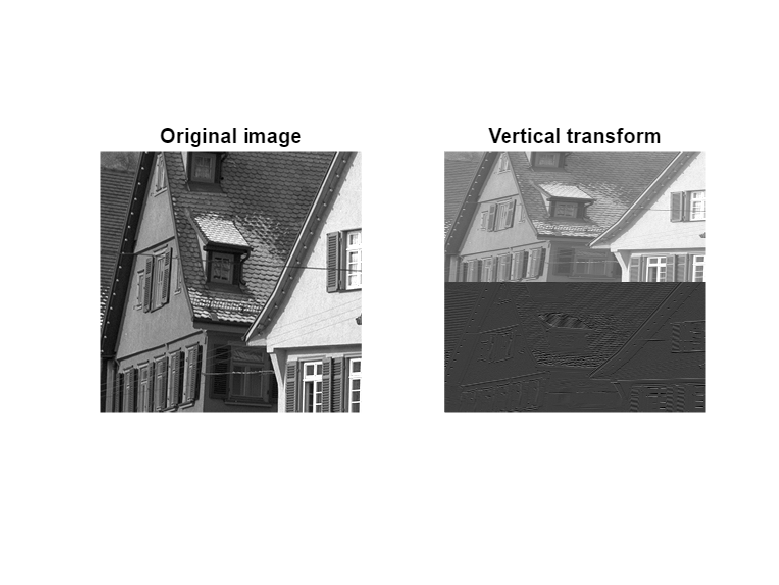

figure;
imageplot(u,'Original image',1,2,1);
imageplot(haarV(u),'Vertical transform',1,2,2);

水平方向の計算を行う関数 haarH は haarVを用いて記述できる．

haarH = @(a)haarV(a')';

haarVとhaarHを組み合わせることで，1レベル分のHWTは以下のように記述できる．

haar = @(a)haarH(haarV(a));

水平，垂直方向の変換を適用すると以下のようになる．

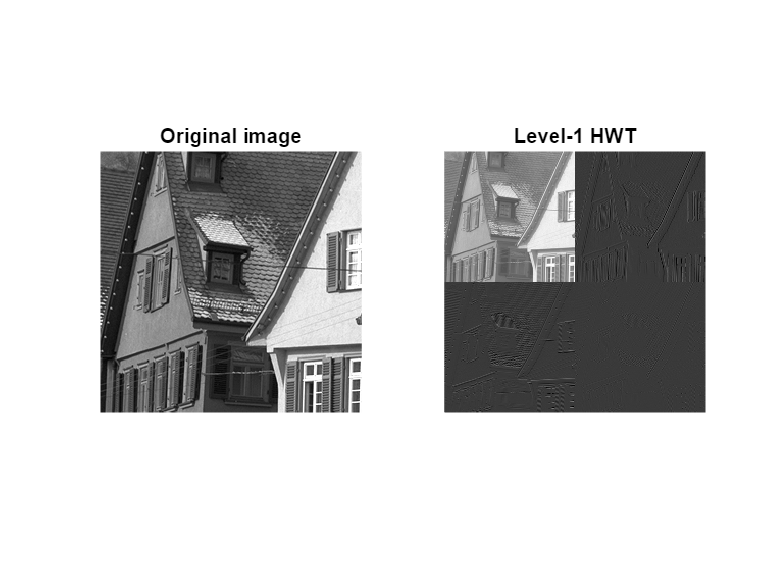

figure;
imageplot(u,'Original image',1,2,1);
imageplot(haar(u),'Level-1 HWT',1,2,2);

見て分かる通り，なめらかな成分と輪郭部が分離できていることがわかる．

さて，このままではただ単に平均と差分を取った画像を表示しただけである．ウェーブレット変換の特徴は，この処理を低周波数成分（つまり，上の画像では左上の係数）に対し繰り返し適用することにある．ここで，2レベルのウェーブレット変換を行ってみよう．

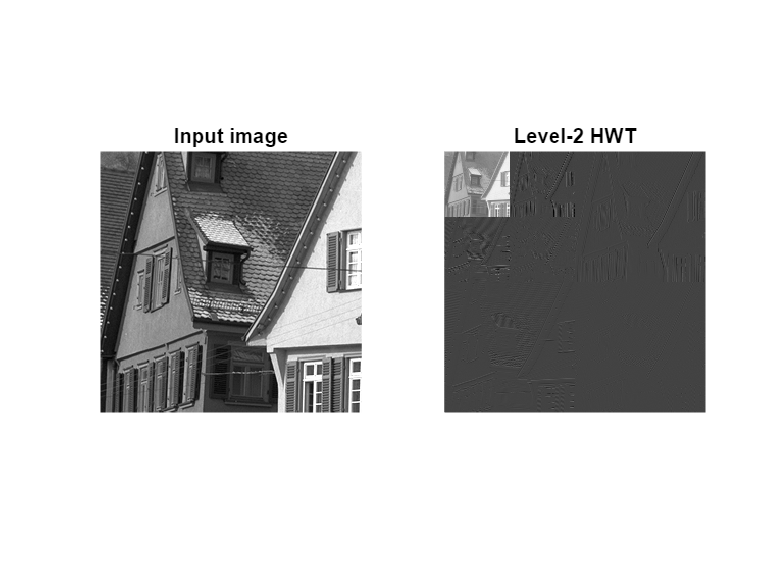

u1 = haar(u); % レベル1
u_tmp = u1(1:n/2, 1:n/2); % レベル2のHWTを行う部分を抽出
u2 = u1;
u2(1:n/2, 1:n/2) = haar(u_tmp); % レベル2

figure;
imageplot(u,'Input image',1,2,1);
imageplot(u2,'Level-2 HWT',1,2,2);

このように繰り返し処理を行うと，「なめらかな成分の輪郭部分」と「なめらかな成分のなめらかな部分」が抽出できていることがわかる．

## **演習問題**

**演習5**: グレースケール画像'house'を読み込み，レベル4のHWTを計算し，原画像と並べて表示せよ．任意のレベル ($1,\dots, \log_2 N$) でHWTを可能にすれば加点する（画像の幅・高さは2のべき乗としてよい）．また，関数 norm を用いて原画像とHWT係数それぞれのノルムを計算し，一致することを確かめよ（変換前後でエネルギーが保存されている）．

name = 'house';
u = load_image(name,[]);
n = length(u);

N = 4 %レベルの指定

N = 4

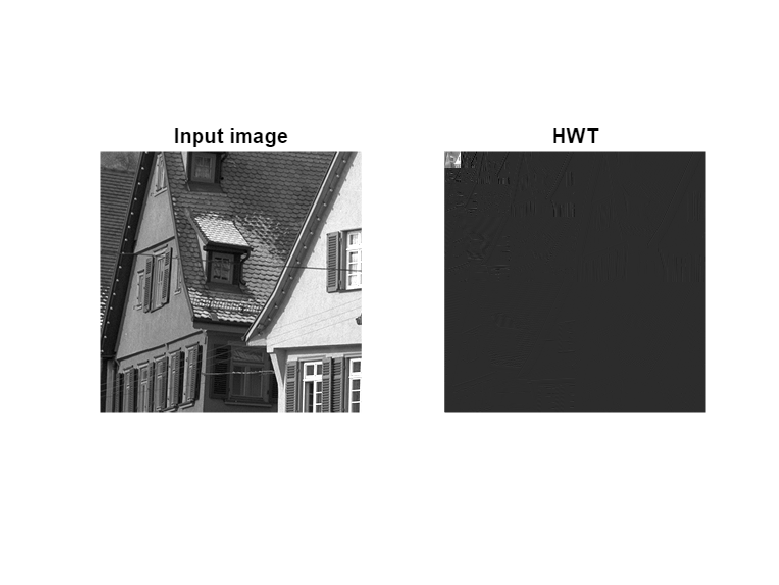

u1 = haar(u);
for i = 1:N-1
    u_tmp = u1(1:n/(2^i), 1:n/(2^i));
    uh = u1;
    uh(1:n/(2^i), 1:n/(2^i)) = haar(u_tmp);
    u1 = uh;
end

figure;
imageplot(u,'Input image',1,2,1);
imageplot(uh,'HWT',1,2,2);


norm(u)

ans = 2.9743e+04

norm(uh)

ans = 2.9705e+04